7.6 Flow Across Banks of Tubes 

Fundamentals of Heat and Mass Transfer, 8th Edition

Table for C and M values

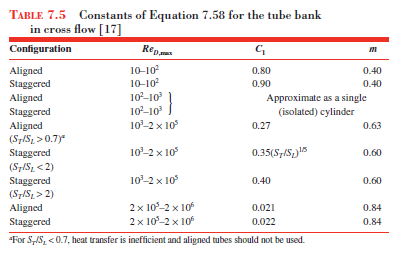

Table for C and M coeffiecents. 

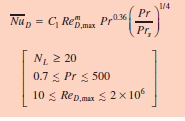

At least 20 tubes(**5 not 20 need correction factor**)

Prandlt number range, Reynolds number range

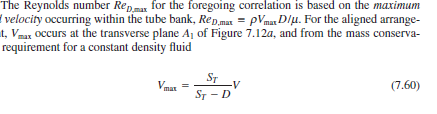

Input vector creation and graphing

AirSpeed = 0:0.1:10;
 tempLow = 40+ 273.15;
    battTemp = 50+ 273.15;
    tempHigh = 42.57 + 273.15;
y = Heatloss(AirSpeed)

densityAir = 1.1274

thermMassAir = 1.0069e+03

ReynoldsNumber = 1.0e+05 *

         0    0.0122    0.0245    0.0367    0.0489    0.0612    0.0734    0.0856    0.0979    0.1101    0.1223    0.1346    0.1468    0.1590    0.1713    0.1835    0.1957    0.2079    0.2202    0.2324    0.2446    0.2569    0.2691    0.2813    0.2936    0.3058    0.3180    0.3303    0.3425    0.3547    0.3670    0.3792    0.3914    0.4037    0.4159    0.4281    0.4404    0.4526    0.4648    0.4771    0.4893    0.5015    0.5138    0.5260    0.5382    0.5504    0.5627    0.5749    0.5871    0.5994


To = 44.9771

qPrimeLadjust = 1.0e+03 *

         0    0.0919    0.1392    0.1776    0.2110    0.2413    0.2691    0.2952    0.3198    0.3433    0.3657    0.3872    0.4079    0.4280    0.4475    0.4664    0.4848    0.5028    0.5203    0.5375    0.5542    0.5707    0.5869    0.6027    0.6183    0.6337    0.6487    0.6636    0.6782    0.6927    0.7069    0.7209    0.7348    0.7485    0.7620    0.7754    0.7886    0.8017    0.8146    0.8274    0.8401    0.8526    0.8650    0.8773    0.8895    0.9016    0.9136    0.9254    0.9372    0.9489


y = 1.0e+03 *

         0    0.0919    0.1392    0.1776    0.2110    0.2413    0.2691    0.2952    0.3198    0.3433    0.3657    0.3872    0.4079    0.4280    0.4475    0.4664    0.4848    0.5028    0.5203    0.5375    0.5542    0.5707    0.5869    0.6027    0.6183    0.6337    0.6487    0.6636    0.6782    0.6927    0.7069    0.7209    0.7348    0.7485    0.7620    0.7754    0.7886    0.8017    0.8146    0.8274    0.8401    0.8526    0.8650    0.8773    0.8895    0.9016    0.9136    0.9254    0.9372    0.9489


hold on
ylabel('HeatLoss[w]');
plot(AirSpeed,y,'.')
%yyaxis right
%plot(z,AirSpeed,'.')
xlabel('AirSpeed at Entrance [m/s]');
%ylabel('Ploss');
var2 = battTemp-273.15;
var1 = tempLow-273;
title_string = sprintf("AirSpeed Vs Heatloss at Ambient %.2f C and Battery Temp %.2f",var1,var2)

title_string = "AirSpeed Vs Heatloss at Ambient 40.15 C and Battery Temp 50.00"

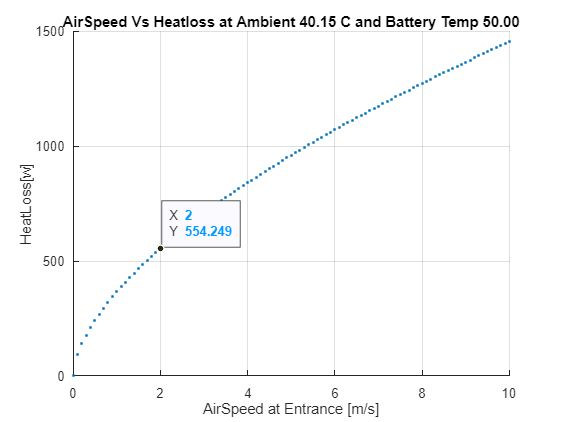

title(title_string)
grid on;
hold off

function HeatLoss = Heatloss(AirSpeed)


Basic

%Reynolds Number Calcs
    BattColumns = 5;
    BatteryRows =23;
    tempLow = 40+ 273.15;
    battTemp = 50+ 273.15;
    tempHigh = 42.57 + 273.15;
    DiameterCells = 18.3/1000; % CHANGE THIS BECAUSE NO GAP




    dynViscosity = py.CoolProp.CoolProp.PropsSI('V', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    densityAir = py.CoolProp.CoolProp.PropsSI('D', 'T', tempLow, 'P|not_imposed', 101325, 'air')
    thermCond = py.CoolProp.CoolProp.PropsSI('L', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    ConstPNum = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    thermMassAir = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air')
    KinViscosity = dynViscosity/densityAir;


% Vert vs Horiz Spacing
    St = 20.066/1000;% spacing between columns
    Sl = 0.98*25.4/1000;%center spacing in direction of initial airflow
    
    Vmax =  St.*AirSpeed./(St-DiameterCells);

    ReynoldsNumber =  Vmax * DiameterCells / KinViscosity % WILL have to update C1 and M Manually before IF statements. 
    PrandtlAirLow = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    PrandtlAirHigh = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempHigh, 'P|not_imposed', 101325, 'air');

    C1 = 0.35*(St/Sl)^(1/5);
    mVal = 0.6; % Table
    C2 = 0.95; %Table (correction factor for 5)



    NusseltD = C2*C1*ReynoldsNumber.^mVal.*(PrandtlAirLow.^0.36).*(PrandtlAirLow./PrandtlAirHigh).^(0.25);
    Hline = NusseltD*thermCond/DiameterCells;

Adjusted Delta for warming


    insideVarTop = (-pi*DiameterCells*(BattColumns*BatteryRows)*Hline);

    insideVarBot = (densityAir.*AirSpeed.*(BatteryRows)*St*ConstPNum);

    adjDelTso = (battTemp - tempHigh)/(battTemp - tempLow) * exp(insideVarTop/insideVarBot);
    To = -((battTemp - tempLow) * exp(insideVarTop/insideVarBot))+battTemp -273.15

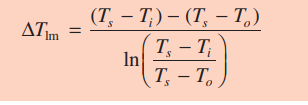

    deltTlm = (battTemp-tempLow)-(adjDelTso)/(log((battTemp-tempLow)/(adjDelTso)));

    qPrime = (BatteryRows*BattColumns)*(Hline*pi*DiameterCells*deltTlm);%in KW per m
    qPrimeLadjust = qPrime*0.047%Temp dissapated
    areaPath = St*BattColumns*0.065;

pressure loss

    Pt = St/DiameterCells;
    Pl = Sl/DiameterCells;
    PTPL = (Pt-1)/(Pl-1);

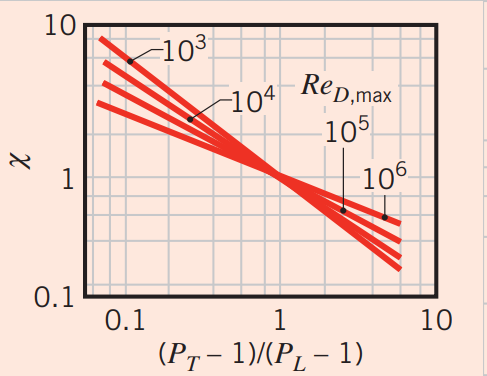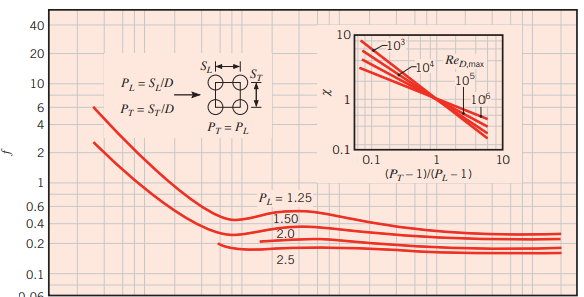

    fancyX = 1.4;
    fricFactor = 0.22;

    deltPLoss = 5.* fancyX .* (densityAir./2.*Vmax.^2) .* fricFactor;

    HeatLoss = qPrimeLadjust;

end